clear all

% This script changes all interpreters from tex to latex. 
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

tic
system_name = 'ieee9'

system_name = 'ieee9'

selectBuses = 3

selectBuses = 3

sampling_rate = 0.3/30;
T = 15%Window size in seconds

T = 15

W = T/sampling_rate

W = 1500

bifurcation_limit  = 0.90

bifurcation_limit = 0.9000

xlsxname = strcat(system_name,'_outfile.xlsx')

xlsxname = 'ieee9_outfile.xlsx'

opts = detectImportOptions(xlsxname, 'NumHeaderLines', 3);
opts.VariableNamingRule = 'modify';
xlsxtable = readtable(xlsxname, opts);

string0 = 'Time';
string1 = 'POWR';
string2 = 'BUS';
string3 = 'PLOD';
string4 = 'FREQ';
string5 = 'VOLT';
string6 = 'CKT';
string7 = 'MVA';

varNames = xlsxtable.Properties.VariableNames;
times = xlsxtable(:, contains(varNames,string0));
times.Properties.VariableNames = {'time'};
rows = times.time > 1.0;
times = times.time(times.time > 1.0);
% segregating the 'normal' run from 
% the constant load increment run

colors = [ [18,14,249]
    [67,127,29] 
    [230,43,52]
   [7,7,7]]/255;

pgens = xlsxtable(rows, contains(varNames, string1) ...
    & contains(varNames, string2));
ploads = xlsxtable(rows, contains(varNames, string3));
freqs = xlsxtable(rows,contains(varNames,string4));

volts = xlsxtable(rows, contains(varNames, string5));
numIterations = size(volts,1);
numBuses = size(volts,2)

numBuses = 9

voltage_selectBuses = volts{:,selectBuses};
[voltageSamplingStartsFrom, startIdx] = max(voltage_selectBuses)

voltageSamplingStartsFrom = 1.0248

startIdx = 1

bifurcationIdx = find(voltage_selectBuses < bifurcation_limit,...
    1, 'first')

bifurcationIdx = 8568

lastIdx = length(voltage_selectBuses)

lastIdx = 10724

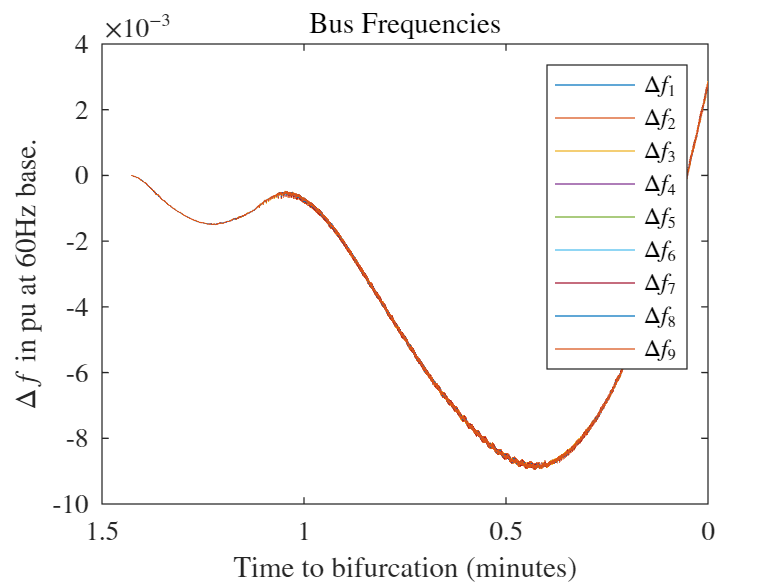


mvaflows = xlsxtable(rows, contains(varNames, string6) ...
    & contains(varNames, string7));

indicesToPlot1 = 1:bifurcationIdx;
xaxis1 = (bifurcationIdx - indicesToPlot1)*sampling_rate/(60);

%plot frequencies
figure()
p1 = plot(xaxis1, freqs{indicesToPlot1,1:9});
xlabel1 = xlabel('Time to bifurcation (minutes)');
set(gca,'xdir','reverse')
title1 = title('Bus Frequencies');
set(title1,'Interpreter', 'Latex');
ylabel1 = ylabel('$\Delta f$ in pu at 60Hz base.');
set(ylabel1,'Interpreter', 'Latex');
if strcmp(system_name,'ieee9')
    leg1 = legend('$\Delta f_1$', '$\Delta f_2$', '$\Delta f_3$', ...
    '$\Delta f_4$', '$\Delta f_5$', '$\Delta f_6$', ...
    '$\Delta f_7$', '$\Delta f_8$', '$\Delta f_9$');
elseif strcmp(system_name,'ieee39')
    leg1 = legend('$P_{Gen} 30$', '$P_{Gen} 31$', 'and so on');
else
    legend;
end
set(leg1, 'Interpreter', 'Latex');

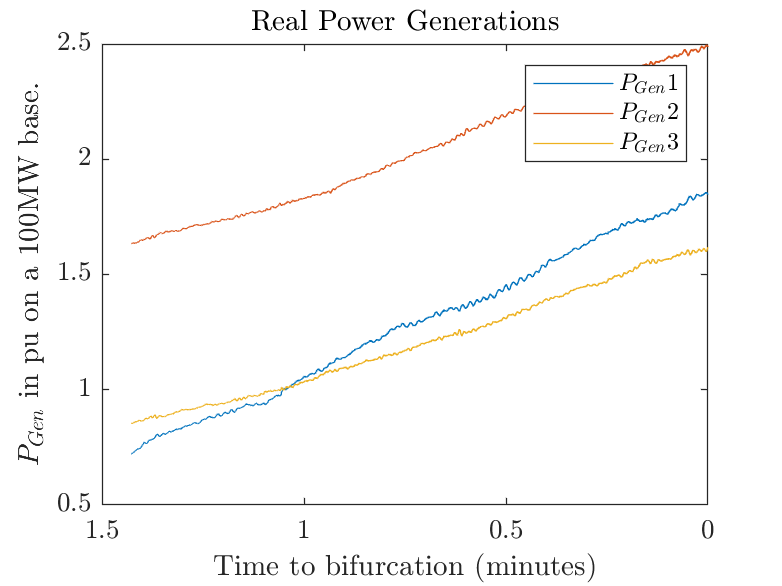


figure()
p1 = plot(xaxis1, pgens{indicesToPlot1,1:3});
xlabel1 = xlabel('Time to bifurcation (minutes)');
set(xlabel1,'Interpreter', 'Latex');
set(gca,'xdir','reverse')
title('Real Power Generations');
ylabel1 = ylabel('$P_{Gen}$ in pu on a 100MW base.');
set(ylabel1,'Interpreter', 'Latex');
if strcmp(system_name,'ieee9')
    leg1 = legend('$P_{Gen} 1$', '$P_{Gen} 2$', '$P_{Gen} 3$');
elseif strcmp(system_name,'ieee39')
    leg1 = legend('$P_{Gen} 30$', '$P_{Gen} 31$', 'and so on');
else
    legend;
end
set(leg1, 'Interpreter', 'Latex');

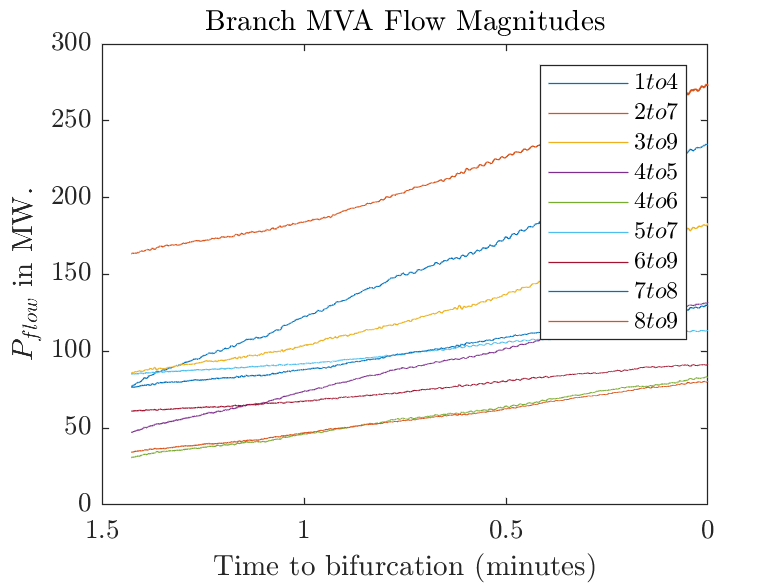


%plot mvaflows
figure()
p1 = plot(xaxis1, ...
    mvaflows{indicesToPlot1,[1 2 3 5 6 8 10 13 15]});
xlabel1 = xlabel('Time to bifurcation (minutes)');
set(gca,'xdir','reverse')
title1 = title('Branch MVA Flow Magnitudes');
set(title1,'Interpreter', 'Latex');
ylabel1 = ylabel('$P_{flow}$ in MW.');
set(ylabel1,'Interpreter', 'Latex');
if strcmp(system_name,'ieee9')
    leg1 = legend('$1 to 4$', '$2 to 7$', '$3 to 9$', ...
    '$4 to 5$', '$4 to 6$', '$5 to 7$', ...
    '$6 to 9$', '$7 to 8$', '$8 to 9$');
elseif strcmp(system_name,'ieee39')
    leg1 = legend('$P_{Gen} 30$', '$P_{Gen} 31$', 'and so on');
else
    legend;
end
set(leg1, 'Interpreter', 'Latex');

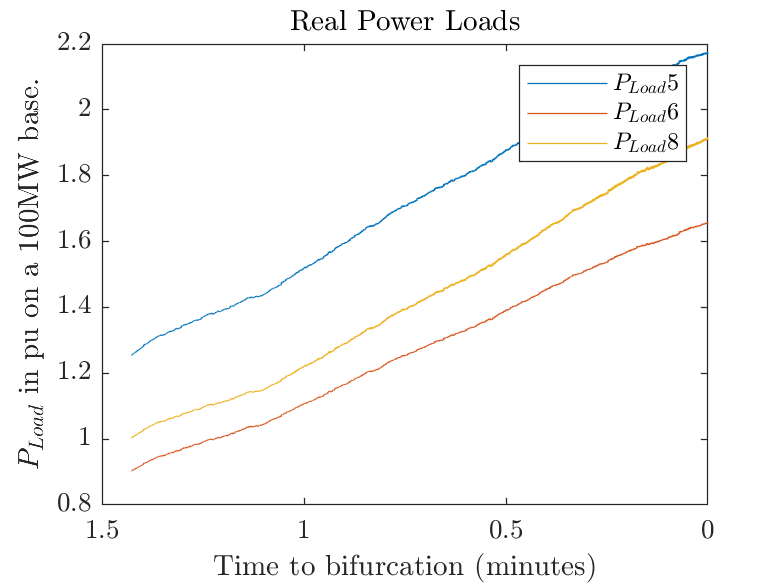


figure()
p2 = plot(xaxis1, ploads{indicesToPlot1,1:3});
xlabel2 = xlabel('Time to bifurcation (minutes)');
set(gca,'xdir','reverse')
title('Real Power Loads')
ylabel2 = ylabel('$P_{Load}$ in pu on a 100MW base.');
set(ylabel2,'Interpreter', 'Latex');
if strcmp(system_name,'ieee9')
    leg2 = legend('$P_{Load} 5$', '$P_{Load} 6$', '$P_{Load} 8$');
elseif strcmp(system_name,'ieee39')
    leg2 = legend('$P_{Load} 1$', '$P_{Load} 231$', 'and so on');
else
    legend;
end

% set(leg2, 'Interpreter', 'Latex');

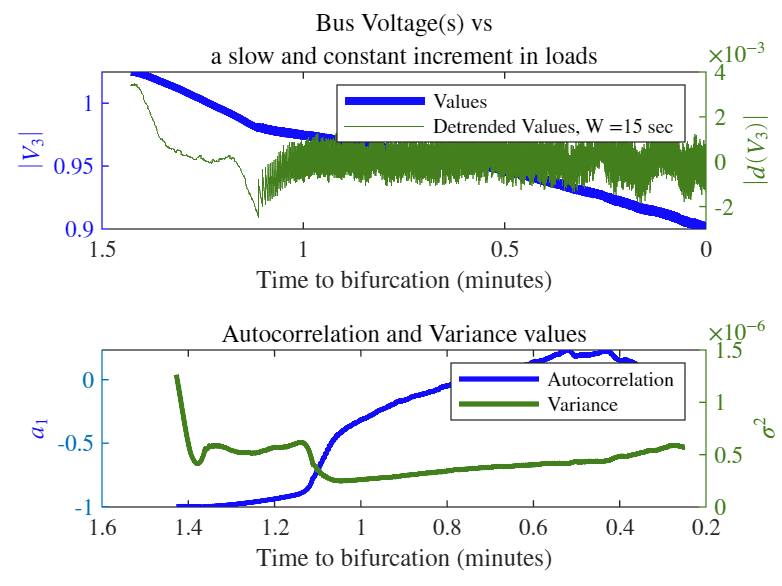

smoothedData = smoothdata(...
    voltage_selectBuses(1:end), 'gaussian', W);

voltage_detrended = voltage_selectBuses - smoothedData;

selectBusNames = string(selectBuses);

indicesToPlot2 = 1:bifurcationIdx-W;
xaxis2 = (bifurcationIdx - indicesToPlot2)*sampling_rate/(60);

figure(2)
subplot(2,1,1)
busesPlotted = 0;
yyaxis left

for i = selectBuses
    set(gca,'xdir','reverse')
    p1 = plot(xaxis1, voltage_selectBuses(indicesToPlot1));
    p1.Color = colors(mod(busesPlotted,4)+1,:);
    p1.LineStyle = '-';
    p1.LineWidth = 3.0;
    busesPlotted = busesPlotted + 1;
end

labelVoltage1 = strcat('$|V_',selectBusNames);
labelVoltage1 = strcat(labelVoltage1,'|$');
ylabel1 = ylabel(labelVoltage1);
ylabel1.Color = colors(1,:);
yticks1 = yticks;
set(gca,'ycolor',colors(1,:))

yyaxis right

for i = selectBuses
    set(gca,'xdir','reverse')
    p2 = plot(xaxis1, voltage_detrended(indicesToPlot1));
    p2.Color = colors(mod(busesPlotted,4)+1,:);
    p2.LineStyle = '-';
    p2.LineWidth = 0.05;
    busesPlotted = busesPlotted + 1;
end

labelVoltage2 = strcat('$|d(V_',selectBusNames);
labelVoltage2 = strcat(labelVoltage2,')|$');
ylabel2 = ylabel(labelVoltage2);
ylabel2.Color = colors(2,:);
yticks2 = yticks;
set(gca,'ycolor',colors(2,:))

xlabel1 = xlabel('Time to bifurcation (minutes)');

legend('Values', ...
    strcat(strcat('Detrended Values, W = ', string(T)), ' sec'));

title('Bus Voltage(s) vs', ...
    'a slow and constant increment in loads');

ar1_vector = zeros(bifurcationIdx-W,1);
var_vector = zeros(bifurcationIdx-W,1);

for startingSample = 1:bifurcationIdx-W
    sys = ar(voltage_detrended(startingSample:startingSample+W-1), ...
        1, 'ls');
    [num,den] = tfdata(sys,'v');
%     a1 = abs(den(2));
    a1 = den(2);
    ar1_vector(startingSample) = a1;
    sigma_squared = ...
        var(voltage_detrended(startingSample:startingSample+W-1));
    var_vector(startingSample) = sigma_squared;
end

subplot(2,1,2)
yyaxis left
set(gca,'xdir','reverse')
p3 = plot(xaxis2, ar1_vector);
p3.LineWidth = 2.0;
p3.Color = colors(1,:);
yticks3 = yticks;
ylabel3 = ylabel('$a_1$');
ylabel3.Color = colors(1,:);
hold on;
yyaxis right
ylabel4 = ylabel('$\sigma^2$');
ylabel4.Color = colors(2,:);
yticks4 = yticks;
set(gca,'ycolor',colors(2,:))
set(gca,'xdir','reverse')
p4 = plot(xaxis2, var_vector);
p4.LineWidth = 2.0;
p4.Color = colors(2,:);
xlabel2 = xlabel('Time to bifurcation (minutes)');
legend('Autocorrelation','Variance');
title('Autocorrelation and Variance values');
hold off;

snp = 3;
if T < 1
    windowInSec = strcat('point',string(10*T));
else
    windowInSec = string(T);
end
imagePdfName = strcat('volts',selectBusNames,'_snp',string(snp),'_W_',windowInSec)

imagePdfName = "volts3_snp3_W_15"

set(figure(2),'PaperSize',[5.6 4.5]); %set the paper size to what you want  
print(figure(2),imagePdfName,'-dpdf') % then print it

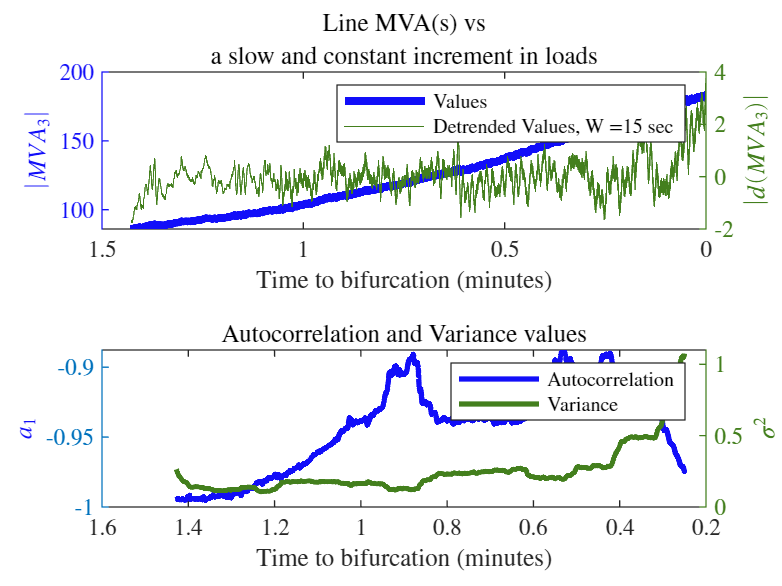

%try analysis with line MVA flows
selectLines = 3;
selectLineNames = string(selectLines);
% mvaselectLines = mvaflows{indicesToPlot1,[1 2 3 5 6 8 10 13 15]};
mvaselectLines = mvaflows{indicesToPlot1,selectLines};
currentSelectLines = mvaselectLines./voltage_selectBuses(indicesToPlot1);
smoothedMVAData = smoothdata(...
    mvaselectLines(1:end), 'gaussian', W);
smoothedCurrentData = smoothdata(...
    currentSelectLines(1:end), 'gaussian', W);
mva_detrended = mvaselectLines - smoothedMVAData;
current_detrended = currentSelectLines - smoothedCurrentData;
    



indicesToPlot2 = 1:bifurcationIdx-W;
xaxis2 = (bifurcationIdx - indicesToPlot2)*sampling_rate/(60);

figure(3)
subplot(2,1,1)
busesPlotted = 0;
yyaxis left

for i = selectLines
    set(gca,'xdir','reverse')
    p1 = plot(xaxis1, mvaselectLines(indicesToPlot1));
    p1.Color = colors(mod(busesPlotted,4)+1,:);
    p1.LineStyle = '-';
    p1.LineWidth = 3.0;
    busesPlotted = busesPlotted + 1;
end

labelVoltage1 = strcat('$|MVA_',selectLineNames);
labelVoltage1 = strcat(labelVoltage1,'|$');
ylabel1 = ylabel(labelVoltage1);
ylabel1.Color = colors(1,:);
yticks1 = yticks;
set(gca,'ycolor',colors(1,:))

yyaxis right

for i = selectBuses
    set(gca,'xdir','reverse')
    p2 = plot(xaxis1, mva_detrended(indicesToPlot1));
    p2.Color = colors(mod(busesPlotted,4)+1,:);
    p2.LineStyle = '-';
    p2.LineWidth = 0.05;
    busesPlotted = busesPlotted + 1;
end

labelVoltage2 = strcat('$|d(MVA_',selectLineNames);
labelVoltage2 = strcat(labelVoltage2,')|$');
ylabel2 = ylabel(labelVoltage2);
ylabel2.Color = colors(2,:);
yticks2 = yticks;
set(gca,'ycolor',colors(2,:))

xlabel1 = xlabel('Time to bifurcation (minutes)');

legend('Values', ...
    strcat(strcat('Detrended Values, W = ', string(T)), ' sec'));

title('Line MVA(s) vs', ...
    'a slow and constant increment in loads');

ar1_vector = zeros(bifurcationIdx-W,1);
var_vector = zeros(bifurcationIdx-W,1);

for startingSample = 1:bifurcationIdx-W
    sys = ar(mva_detrended(startingSample:startingSample+W-1), ...
        1, 'ls');
    [num,den] = tfdata(sys,'v');
%     a1 = abs(den(2));
    a1 = den(2);
    ar1_vector(startingSample) = a1;
    sigma_squared = ...
        var(mva_detrended(startingSample:startingSample+W-1));
    var_vector(startingSample) = sigma_squared;
end

subplot(2,1,2)
yyaxis left
set(gca,'xdir','reverse')
p3 = plot(xaxis2, ar1_vector);
p3.LineWidth = 2.0;
p3.Color = colors(1,:);
yticks3 = yticks;
ylabel3 = ylabel('$a_1$');
ylabel3.Color = colors(1,:);
hold on;
yyaxis right
ylabel4 = ylabel('$\sigma^2$');
ylabel4.Color = colors(2,:);
yticks4 = yticks;
set(gca,'ycolor',colors(2,:))
set(gca,'xdir','reverse')
p4 = plot(xaxis2, var_vector);
p4.LineWidth = 2.0;
p4.Color = colors(2,:);
xlabel2 = xlabel('Time to bifurcation (minutes)');
legend('Autocorrelation','Variance');
title('Autocorrelation and Variance values');

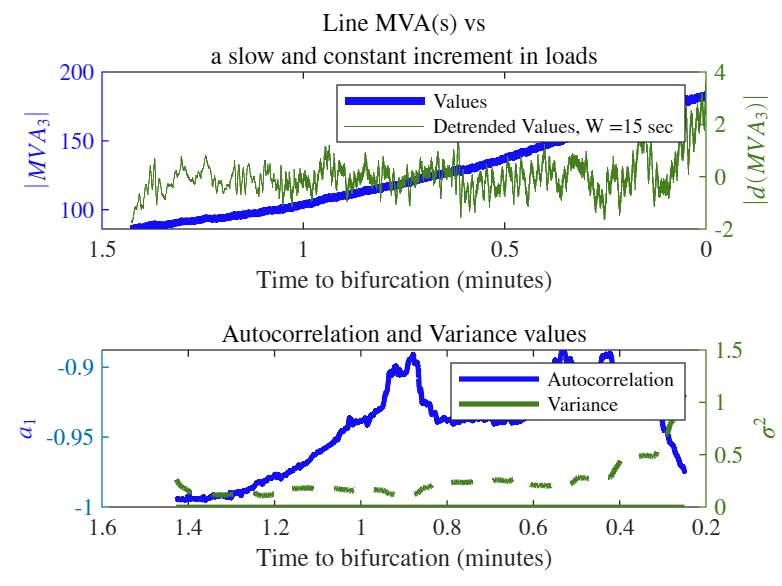

indicesToPlot2 = 1:bifurcationIdx-W;
xaxis2 = (bifurcationIdx - indicesToPlot2)*sampling_rate/(60);

figure(2)
subplot(2,1,1)
busesPlotted = 0;
yyaxis left

for i = selectLines
    set(gca,'xdir','reverse')
    p1 = plot(xaxis1, mvaselectLines(indicesToPlot1));
    p1.Color = colors(mod(busesPlotted,4)+1,:);
    p1.LineStyle = '-';
    p1.LineWidth = 3.0;
    busesPlotted = busesPlotted + 1;
end

labelVoltage1 = strcat('$|MVA_',selectLineNames);
labelVoltage1 = strcat(labelVoltage1,'|$');
ylabel1 = ylabel(labelVoltage1);
ylabel1.Color = colors(1,:);
yticks1 = yticks;
set(gca,'ycolor',colors(1,:))

yyaxis right

for i = selectBuses
    set(gca,'xdir','reverse')
    p2 = plot(xaxis1, mva_detrended(indicesToPlot1));
    p2.Color = colors(mod(busesPlotted,4)+1,:);
    p2.LineStyle = '-';
    p2.LineWidth = 0.05;
    busesPlotted = busesPlotted + 1;
end

labelVoltage2 = strcat('$|d(MVA_',selectBusNames);
labelVoltage2 = strcat(labelVoltage2,')|$');
ylabel2 = ylabel(labelVoltage2);
ylabel2.Color = colors(2,:);
yticks2 = yticks;
set(gca,'ycolor',colors(2,:))

xlabel1 = xlabel('Time to bifurcation (minutes)');

legend('Values', ...
    strcat(strcat('Detrended Values, W = ', string(T)), ' sec'));

title('Line MVA(s) vs', ...
    'a slow and constant increment in loads');

ar1_vector = zeros(bifurcationIdx-W,1);
var_vector = zeros(bifurcationIdx-W,1);

for startingSample = 1:bifurcationIdx-W
    sys = ar(mva_detrended(startingSample:startingSample+W-1), ...
        1, 'ls');
    [num,den] = tfdata(sys,'v');
%     a1 = abs(den(2));
    a1 = den(2);
    ar1_vector(startingSample) = a1;
    sigma_squared = ...
        var(mva_detrended(startingSample:startingSample+W-1));
    var_vector(startingSample) = sigma_squared;
end

subplot(2,1,2)
yyaxis left
set(gca,'xdir','reverse')
p3 = plot(xaxis2, ar1_vector);
p3.LineWidth = 2.0;
p3.Color = colors(1,:);
yticks3 = yticks;
ylabel3 = ylabel('$a_1$');
ylabel3.Color = colors(1,:);
hold on;
yyaxis right
ylabel4 = ylabel('$\sigma^2$');
ylabel4.Color = colors(2,:);
yticks4 = yticks;
set(gca,'ycolor',colors(2,:))
set(gca,'xdir','reverse')
p4 = plot(xaxis2, var_vector);
p4.LineWidth = 2.0;
p4.Color = colors(2,:);
xlabel2 = xlabel('Time to bifurcation (minutes)');
legend('Autocorrelation','Variance');
title('Autocorrelation and Variance values');
hold off;hold off;

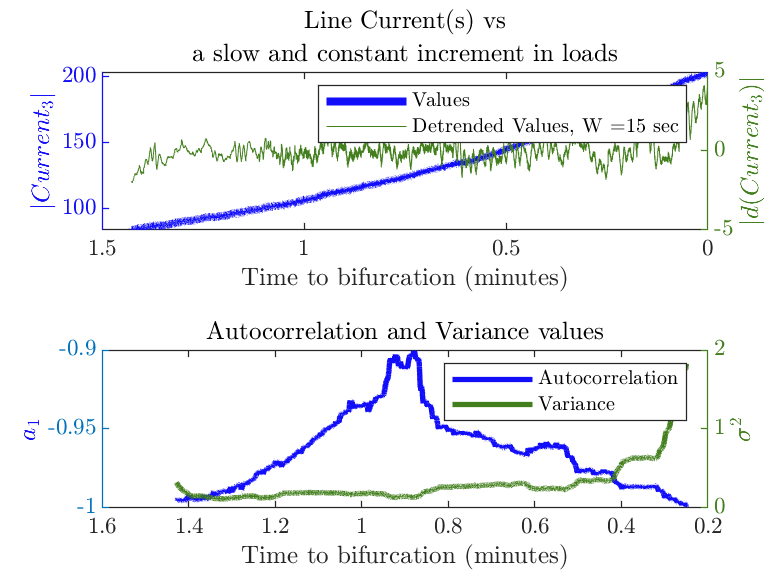


%print current plots
indicesToPlot2 = 1:bifurcationIdx-W;
xaxis2 = (bifurcationIdx - indicesToPlot2)*sampling_rate/(60);

figure(4)
subplot(2,1,1)
busesPlotted = 0;
yyaxis left

for i = selectLines
    set(gca,'xdir','reverse')
    p1 = plot(xaxis1, currentSelectLines(indicesToPlot1));
    p1.Color = colors(mod(busesPlotted,4)+1,:);
    p1.LineStyle = '-';
    p1.LineWidth = 3.0;
    busesPlotted = busesPlotted + 1;
end

labelVoltage1 = strcat('$|Current_',selectLineNames);
labelVoltage1 = strcat(labelVoltage1,'|$');
ylabel1 = ylabel(labelVoltage1);
ylabel1.Color = colors(1,:);
yticks1 = yticks;
set(gca,'ycolor',colors(1,:))

yyaxis right

for i = selectBuses
    set(gca,'xdir','reverse')
    p2 = plot(xaxis1, current_detrended(indicesToPlot1));
    p2.Color = colors(mod(busesPlotted,4)+1,:);
    p2.LineStyle = '-';
    p2.LineWidth = 0.05;
    busesPlotted = busesPlotted + 1;
end

labelVoltage2 = strcat('$|d(Current_',selectLineNames);
labelVoltage2 = strcat(labelVoltage2,')|$');
ylabel2 = ylabel(labelVoltage2);
ylabel2.Color = colors(2,:);
yticks2 = yticks;
set(gca,'ycolor',colors(2,:))

xlabel1 = xlabel('Time to bifurcation (minutes)');

legend('Values', ...
    strcat(strcat('Detrended Values, W = ', string(T)), ' sec'));

title('Line Current(s) vs', ...
    'a slow and constant increment in loads');

ar1_vector = zeros(bifurcationIdx-W,1);
var_vector = zeros(bifurcationIdx-W,1);

for startingSample = 1:bifurcationIdx-W
    sys = ar(current_detrended(startingSample:startingSample+W-1), ...
        1, 'ls');
    [num,den] = tfdata(sys,'v');
%     a1 = abs(den(2));
    a1 = den(2);
    ar1_vector(startingSample) = a1;
    sigma_squared = ...
        var(current_detrended(startingSample:startingSample+W-1));
    var_vector(startingSample) = sigma_squared;
end

subplot(2,1,2)
yyaxis left
set(gca,'xdir','reverse')
p3 = plot(xaxis2, ar1_vector);
p3.LineWidth = 2.0;
p3.Color = colors(1,:);
yticks3 = yticks;
ylabel3 = ylabel('$a_1$');
ylabel3.Color = colors(1,:);
hold on;
yyaxis right
ylabel4 = ylabel('$\sigma^2$');
ylabel4.Color = colors(2,:);
yticks4 = yticks;
set(gca,'ycolor',colors(2,:))
set(gca,'xdir','reverse')
p4 = plot(xaxis2, var_vector);
p4.LineWidth = 2.0;
p4.Color = colors(2,:);
xlabel2 = xlabel('Time to bifurcation (minutes)');
legend('Autocorrelation','Variance');
title('Autocorrelation and Variance values');
hold off;

toc

Elapsed time is 407.307583 seconds.
